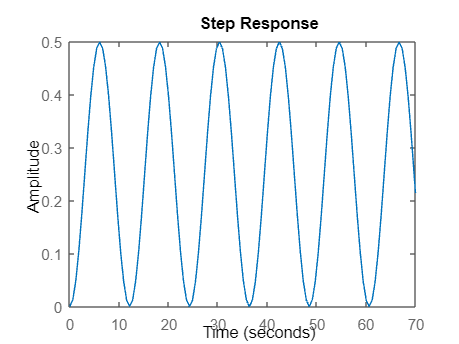

m = 0.02;
R = 0.015;
g = -9.8;
L = 0.34;
d = 0.03;
J = 9.99e-6;
s = tf('s');
P_ball = -m*g*d/(L*(J/R^2+m)*s^2);

Kp = 1;
C = pid(Kp);
sys_cl=feedback(C*P_ball,1);

step(0.25*sys_cl)
axis([0 70 0 0.5])

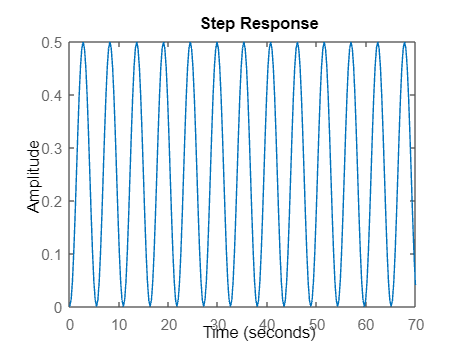


Kp = 5;
C = pid(Kp);
sys_cl=feedback(C*P_ball,1);

step(0.25*sys_cl)
axis([0 70 0 0.5])

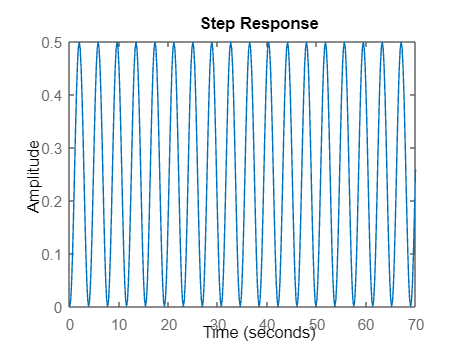


Kp = 10;
C = pid(Kp);
sys_cl=feedback(C*P_ball,1);

step(0.25*sys_cl)
axis([0 70 0 0.5])

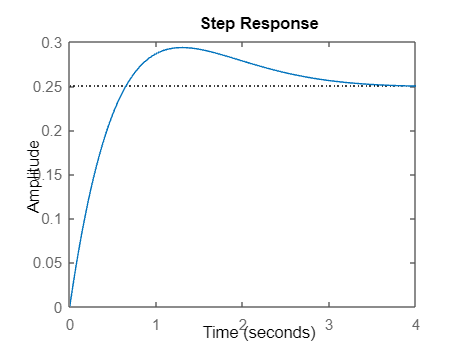




Kp = 10;
Kd = 10;
C = pid(Kp,0,Kd);

sys_cl=feedback(C*P_ball,1);

t=0:0.01:5;
step(0.25*sys_cl)

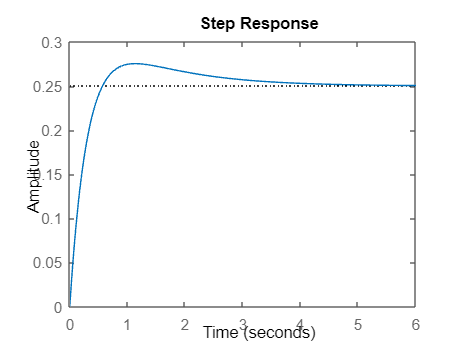


Kp = 10;
Kd = 15;
C = pid(Kp,0,Kd);

sys_cl=feedback(C*P_ball,1);

t=0:0.01:5;
step(0.25*sys_cl)

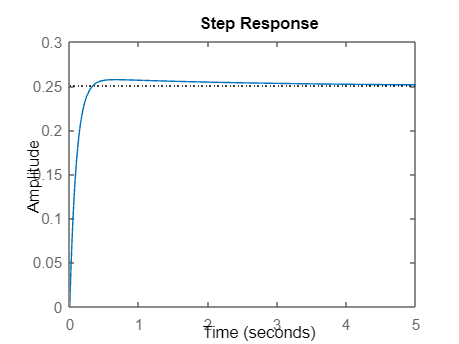



Kp = 15;
Kd = 40;
C = pid(Kp,0,Kd);
sys_cl=feedback(C*P_ball,1);
step(0.25*sys_cl)

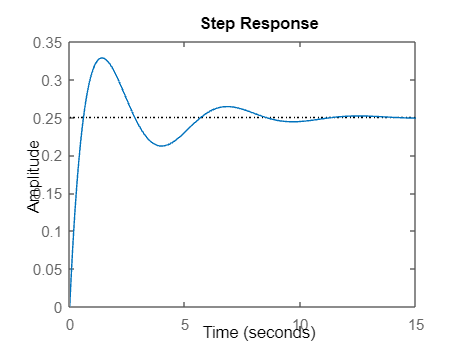




Kp = 10;
Kd = 10;
ki = 10;
C = pid(Kp,ki,Kd);
sys_cl=feedback(C*P_ball,1);
step(0.25*sys_cl)

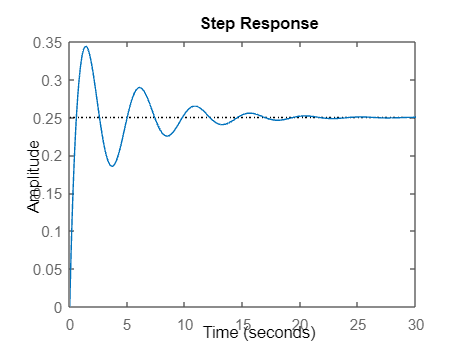


Kp = 10;
Kd = 10;
ki = 15;
C = pid(Kp,ki,Kd);
sys_cl=feedback(C*P_ball,1);
step(0.25*sys_cl)

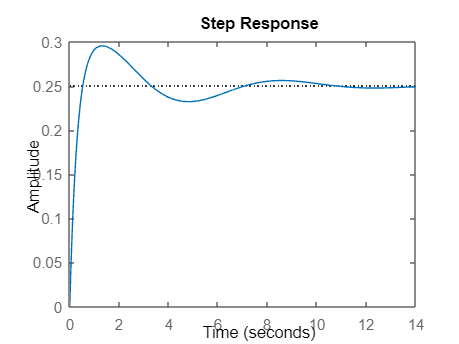


Kp = 10;
Kd = 15;
ki = 10;
C = pid(Kp,ki,Kd);
sys_cl=feedback(C*P_ball,1);
step(0.25*sys_cl)

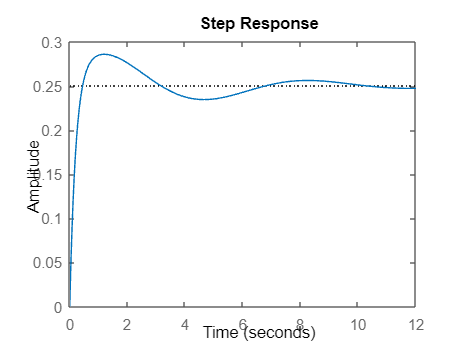


Kp = 12;
Kd = 20;
ki = 15;
C = pid(Kp,ki,Kd);
sys_cl=feedback(C*P_ball,1);
step(0.25*sys_cl)